% Open the file containing the received samples
f2 = fopen('rx1.dat', 'rb');

% read data from the file
tmp = fread(f2, 'float32');

% close the file
fclose(f2);

y_before_trim = tmp(1:2:end)+1i*tmp(2:2:end);
y = y_before_trim;

[y1x1,lag1] = xcorr(y,preamble);
[~, Index] = max(abs(y1x1));
shift = lag1(Index)

shift = 4476725

z = y(shift:end);

% Trim data to manually observed location of received data
%y = y_before_trim(9.5450e6:9.5475e6);

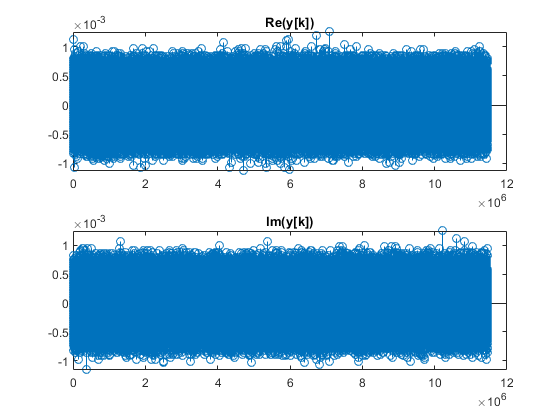

y_real = real(z);
y_imag = imag(z);

figure;
subplot(2, 1, 1);
stem(y_real);
title("Re(y[k])");
subplot(2, 1, 2);
stem(y_imag);
title("Im(y[k])");

% Phase correction
%y_corrected = correct_recieved(y);
% figure;
% subplot(2, 1, 1);
% stem(real(y_corrected));
% title("Re(y[k])");
% subplot(2, 1, 2);
% stem(imag(y_corrected));
% title("Im(y[k])");
figure;
scatter(real(y), imag(y));

Use header and tail flag to determine lag using the xcorr function

%   Signal extraction
O = ones(10000, 1);
[y1, lags] = xcorr(real(PhaseCorrSignal),O);

% figure
% plot(lags, y1)
